# Setup

clear;
clc;
close all;
addpath('Data\');

Metrological input

n_samples = 500;


% METEOROLOGICAL INPUT 
lat=46.07; %latitude in deg
az=0; % panel azimuth in deg (facing south)
tilt=30; % tilt angle in deg
rho=0.2; % substrate reflectance
Data

I0 = 1367; %[W/m^2] solar constant
phi = pi/180*lat; % latit in radianti
gamma = az*pi/180; % azimuth in rad % ELIMINA 
beta = pi/180*tilt; % tilt in rad
DT = Tmax-Tmin; % daily temperature variation

delta = 23.45*pi/180*sin(2*pi*(284+n)/365.25); % declination [rad]
omega_s = acos(-tan(phi)*tan(delta)); % sunrise/sunset angle on ground [rad]
t_sr = -12/pi*omega_s + 12; % sunset time (h) 
t_ss = 12/pi*omega_s + 12; % sunrise time (h) 

Collector data

N=1;             % number of modules installed
A = 2.14;        %[m^2] effective absorber surface
V = 1.7;         % [L] collector liquid content
alpha = 0.95;    % collector absorption
epsilon = 0.04;  % emissions
eta_zero = 0.802;   %optical efficiency at absorber
U = 4.3;            % [W / m^2K]
a1 = 4.28;          % [W / m^2K] coefficients of heat loss
a2 = 0.0064;        % [W / m^2K^2] coefficients of heat loss
flow_rate = 64.2;   % [L/h] recommended flow rate

c_joule = 4200; % J/(kg*K) water specific heat capacity
c = c_joule/3600; % Wh/(kg*K) water specific heat capacity
T_in = 30; % °C
Tin = T_in + 273.15;   % K
water_density = 1;     % [kg/L] water density, assumed constant
m_dot = (flow_rate/3600)*water_density;    % [kg/s] mass flow rate

## Irradiation

Now we can use 2 methods:

- the first method is a semplification and assumes that the ratio of extraterrestrial irradiation on a tilted surface to the extraterrestrial irradiation on a horizontal plane is equal to H0(beta)/H0h. Moreover it can be used only with surfaces that are tilted while facing the equator.

- the second method is used for surfaces tilted in any direction.

We will use the second method because it also allows us to calculate the hourly.

Calculate then the hourly irradiatrion values by using the ratio rt

a_=0.409+0.5016*sin(omega_s-pi/3);
b_=0.6609-0.4767*sin(omega_s-pi/3);


We can now loop along all the months of the year

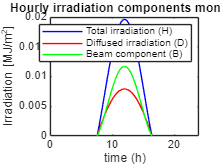

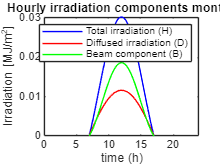

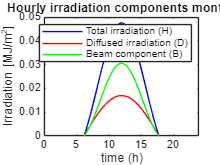

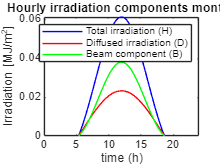

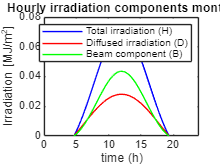

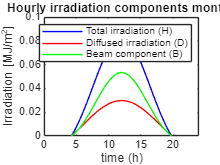

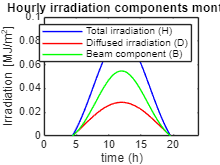

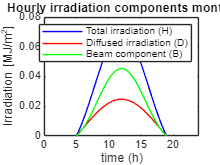

 H_check = zeros(12,1);
 D_check = zeros(12,1);

Ht = zeros(n_samples, 12);
Dt = zeros(n_samples, 12);
Bt = zeros(n_samples, 12);
Hbt = zeros(n_samples, 12);
Ta = zeros(n_samples, 12);
eta = zeros(n_samples, 12);
solar_power = zeros(n_samples, 12);
solar_energy = zeros(12, 1);
collector_power = zeros(n_samples, 12);
collector_energy = zeros(12, 1);
deltaT = zeros(n_samples, 12);  %Tout - Tin (temperature)
time = zeros(n_samples, 12);
Tout = zeros(n_samples, 12);


for i=1:12 % loop over months

    % create timeseries that goes from sunrise to sunset
    time(:, i) = linspace(t_sr(i),t_ss(i),n_samples)';    
    omega = pi/12*(time(:, i)-12); % hour angle of the sun
    dt = time(2, i)-time(1, i);
    domega = omega(2)-omega(1);


    % ambient temperature profile
    Ta(:, i) = (Tmax(i)+Tmin(i))/2 +(Tmax(i)-Tmin(i))/2*cos(2*pi/24*(time(:, i)-tmax)); % [°C] hourly ambient temperature


    % calculate the hourly irradiation values. The total irradiation for
    % each hour is calculated by multiplying these ratios for the average
    % day irradiation (same goes for diffused component), then we calculate
    % the beam component as difference
    rd = pi/24*(cos(omega)-cos(omega_s(i)))/(sin(omega_s(i))-omega_s(i)*cos(omega_s(i)));
    rt = rd.*(a_(i)+b_(i)*cos(omega));
    Dt(:, i) = rd*D(i)*dt/1;    % [MJ/m^2] in a time interval dt
    Ht(:, i) = rt*H(i)*dt/1;    % [MJ/m^2] in a time interval dt
    Bt(:, i) = Ht(:, i) - Dt(:, i);         % [MJ/m^2] in a time interval dt


    % Check if correct
    D_check(i) = sum(Dt(:, i)); % should be the same as D
    H_check(i) = sum(Ht(:, i)); % should be the same as H
    
    %Now that we calculated the hourly irradiation, we need to compute how
    %much of it goes on our tilted surface

    % Compute: thetai (angle of incidence of the sun rays on tilted plane)
    % and thetaz (solar zenith angle)

    cosThetaz=cos(omega)*cos(delta(i))*cos(phi)+sin(delta(i))*sin(phi);
    cosThetai = cos(beta)*(sin(delta(i))*sin(phi) + cos(delta(i))*cos(omega)*cos(phi)) - sin(beta)*(cos(gamma)*(cos(phi)*sin(delta(i)) - cos(delta(i))*cos(omega)*sin(phi)) - cos(delta(i))*sin(gamma)*sin(omega));

    Rt=cosThetai./cosThetaz;


    Hbt(:, i) = (Bt(:, i).*Rt+Dt(:, i).*((1+cos(beta))/2)+((1-cos(beta))/2)*rho.*Ht(:, i))*1e6/(3600*dt); % [W/m^2] radiation (instantaneous power, function fo time)
    %Hbt(:, i) = (Bt(:, i).*Rt+Dt(:, i).*((1+cos(beta))/2)+((1-cos(beta))/2)*rho.*Ht(:, i))*1e6*dt/(3600); % [W/m^2] radiation (instantaneous power, function fo time)
    Hbt(1, i) = 0; Hbt(end, i) = 0; 
    Hbt(Hbt(:, i)<0, i) = 0;
    % Hbt_(cosThetai<0 | cosThetaz<0)= 0;

    
    
    %Plots
    figure(i)
    plot(time(:, i), Ht(:, i), 'Color','b', 'LineStyle','-')
    hold on
    %plot(time, Hbt, 'Color','b', 'LineStyle','--')
    plot(time(:, i), Dt(:, i), 'Color','r', 'LineStyle','-')
    plot(time(:, i), Bt(:, i), 'Color','g', 'LineStyle','-')
    xlabel('time (h)')
    xlim([0 24])
    ylabel('Irradiation [MJ/m^2]')
    legend('Total irradiation (H)', 'Diffused irradiation (D)', 'Beam component (B)')
    title(strcat('Hourly irradiation components month ', num2str(i)))
    hold off


    %Now calculate 

    eta(:, i) = eta_zero - U * (T_in - Ta(:, i)) ./ Hbt(:, i);

    ind = find(eta > 0);
    eta(eta(:, i)<0, i) = 0;
    eta(isnan(eta(:, i)), i) = 0;

    %Total solar power on tilted panel

    solar_power(:, i) = Hbt(:, i).*A;

    collector_power(:, i) = eta(:, i).*Hbt(:, i).*A;
    collector_power(collector_power(:, i)<0, i) = 0;
    collector_power(isnan(collector_power(:, i)), i) = 0;

    %Knowing the power captured by the collector, the fluid flow rate (assumed constant at the recommended value) and
    %the specific heat, we can calculate the temperature change of the
    %fluid between the entrance and the exit of the collector.

    deltaT(:, i) = collector_power(:, i)/(flow_rate*c);
    Tout(:, i) = T_in + deltaT(:, i);


    % calculate solar and collector energy as integral of the power

    collector_energy(i) = trapz(time(:, i) ,collector_power(:, i));  % [Wh] energy generated in the avg day of the current month
    solar_energy(i) = trapz(time(:, i), solar_power(:, i));  % [Wh] energy generated in the avg day of the current month

end

Now we can multiply the average energy production in the day of each month by the number of days in the month, sum everything together and obtain the total energy produced in a year.

We will calculate the collector efficiency by divinding the yearly collector energy by the yearly solar energy hitting the panel.

collector_energy_year = sum(collector_energy.*Month_day);  % Wh
solar_energy_year = sum(solar_energy.*Month_day);          % Wh

yearly_eff = collector_energy_year/solar_energy_year;

disp(['In average, during a year a total of ', num2str(solar_energy_year/1e6),' MWh hit the solar panel. ' ...
    'However, only ', num2str(collector_energy_year/1e6), ' MWh get captured. ' ...
    'This means that the collector has an average yearly efficiency of ', num2str(yearly_eff*100), '%.']);

In average, during a year a total of 3.5439 MWh hit the solar panel. However, only 2.3047 MWh get captured. This means that the collector has an average yearly efficiency of 65.0317%.


We expect that the average efficiency that we measured is very close, if not identical, to the average value of eta in the whole year.

eta = eta(:);
eta_mean = mean(eta);

This is not as we expected since we thought that the average value of eta would be higher. Try to filter the values where eta is zero

eta_mean_filtered = mean(eta(eta>0));

It is still lower than expected